# In Search Of A Squared Magic Square

A tool for examining the patterns that result from summing multiple sets of 3 square numbers, in hopes of finding a 3×3 magic square where every element is a perfect square

Each number is given a unique color by converting its decimal value to hexadecimal value to RGB value 

### Starting Values

Set *n*, *a*, & *b* to desired values

n = 1675; %STARTING SQUARE - no more than approximately 2200
N = n^2;

%for an a by b matrix
a = 100;
b = 100; 
%best to keep values around 100

### Error Handling

Ensure decimals can be converted to 6 digit hex strings

if (N +(n+a)^2 +(n+b)^2) > 16777215
    error("hex value limit exceeded - try a smaller n value")
end

### Figure Creation

figure('Name','Magic','NumberTitle','off')
title([num2str(n),'^2 + ',num2str(n+1),'^2 + ',num2str(n+2),'^2 up to ',...
    num2str(n),'^2 + ',num2str(n+a+1),'^2 + ',num2str(n+b+2),'^2'])
xlim([0 a]);
ylim([0 b]);

### Plotting the Colored Squares

Figure creation may take a moment depending on a and b values

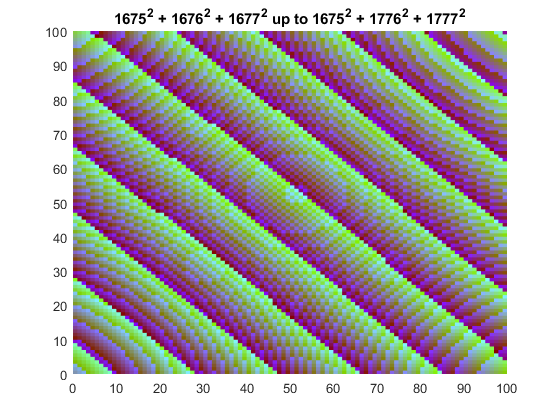

M = zeros(a,b);
for i = 1:b
    for j = 1:a
        M(i,j) = (N+(n+i+1)^2+(j+n)^2);
        hex = dec2hex(M(i,j),6);
        rectangle('Position', [i-1 j-1 i j], ...
            'FaceColor', (1/255)*hex2rgb(hex), ...
            'EdgeColor', 'none');
    end
end
set(gcf,'Visible','on'); %show result 

### Hex to RGB function

All credit to original author

function RGB = hex2rgb(HEX)
% HEX2RGB - convert hexadecimal color strings to RGB values
%
%   RGB = HEX2RGB(HEX) converts the hexadimal color string HEX to its
%   corresponding RGB values. RGB has three columns representing the red,
%   green and blue component of the color.  
%   For a cell array of color strings, RGB will have as many rows as
%   elements of the cell array. For a character array HEX, RGB will have as
%   many rows as HEX. 
%
%   Three-digit hexadecimal color strings are expanded to six-digit strings
%   by doubling each digit (i.e., XYZ -> XXYYZZ).
%   
%   Examples:
%     hex2rgb('556b2f') % 6 digit string
%       % -> [ 85 107  47]
%     hex2rgb('f0f')    % 3 digit string  
%       % -> [255   0 255] 
%     hex2rgb({'8B4513','FF0'})  % cell array
%       % -> [139 69 19 ; 255 255 0]
%     hex2rgb(['FF6347' ; '40E0D0']) % character array with multiple rows
%       % -> [255 99 71 ; 64 224 208]
%
%   Hexadecimal color strings are three-byte triplets representing the red,
%   green and blue component. One byte represents a number in the range 00
%   to FF (in hexadecimal notation). More information:
%   http://en.wikipedia.org/wiki/Web_colors
%
%   See also HEX2DEC

% Created in Matlab R2011b 
% version 1.0 (feb 2014)
% (c) Jos van der Geest
% email: jos@jasen.nl

% History
% 1.0 (feb 2014) - created

% check the input
if ~iscellstr(HEX)
    if ischar(HEX)
       HEX = cellstr(HEX) ;
    else
       error('Input should be a cell array of strings, or a character matrix.') ; 
    end
end

HEX = upper(HEX) ;

tf = cellfun(@(S) numel(S)==3, HEX) ;
if any(~tf) && ~all(cellfun(@(S) numel(S)==6, HEX(~tf)))
    error('All hexadecimal color strings should be 3 or 6 characters long.') ;
elseif any(tf)
    % convert any 3 character arrays to 6 character arrays
    % xyz -> xxyyzz
    HEX(tf) = cellfun(@(S) S([1 1 2 2 3 3]), HEX(tf),'un',0) ;
end

% convert to numbers between 0 and 15
HEX = double(char(HEX)) ;
tf = HEX > 64 ; % letters
HEX(~tf) = HEX(~tf) - '0' ;     % numbers:  0-9
HEX(tf)  = HEX(tf) - 'A' + 10 ; % letters: 10-15

if any(HEX(:) < 0) || any(HEX(:) > 15)
    error('Input string found with characters other than 0-9, a-f, or A-F.') ;
end

% reshape in two rows, each column is a byte (xy)
% the first 3 columns are the RGB values of the first column, etc.
HEX = reshape(HEX.',2,[]) ;
% [x ; y] -> [16*x ; y] 
HEX(1,:) = 16 * HEX(1,:) ;
% -> 16*x+y
RGB = sum(HEX,1) ; 

% reshape in RGB triplet
RGB = reshape(RGB,3,[]) ; % color triplets
RGB = RGB.' ; % we want color as rows
end